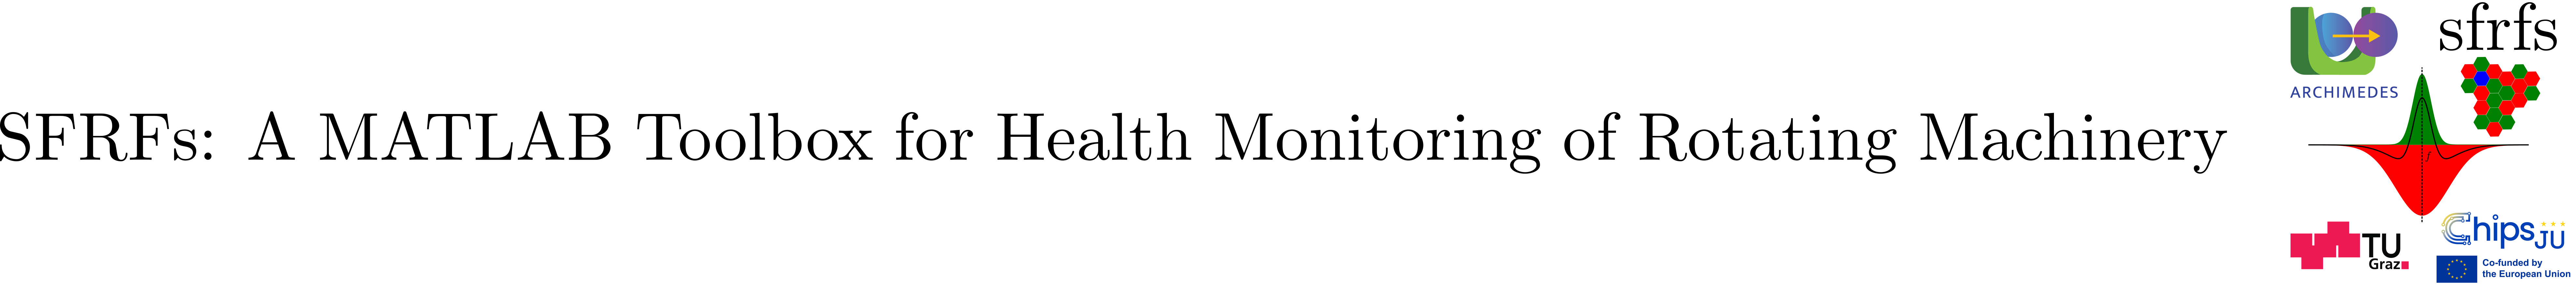

# GainFunctionsTableSchema

## Summary

`GainFunctionsTableSchema` extends [`FaultBandsTableSchema`](matlab:open('./FaultBandsTableSchema.mlx')) with columns specific to receptive field gain functions (RFGFs) and their computed responses.

## Description

Gain-functions tables represent the transition from diagnostic knowledge (fault bands) to perceptual artifacts (frequency-bank masks and SFRF responses).

They retain the full fault-condition key inherited from `FaultBandsTableSchema` and add columns storing the masks produced by `ReceptiveFieldGainFunctions` and the corresponding SFRF values.

### Inherited columns

From `FaultBandsTableSchema` (and its base):

- `FAULTGROUP` – Fault group identifier

- `SPEED` – Shaft speed (Hz)

- `LOAD` – Load (kN)

- `DESCRIPTION` – Fault description

- `RECEPTIVEFIELDBANDS` – Fault-band definitions

### Defined columns

### Notes

- `FREQUENCYBANKMASKS` stores the *perceptual filters* derived from fault bands.

- `SFRFS` stores the corresponding responses, closing the loop from knowledge to perception.

- This schema is the primary interface between `ReceptiveFieldGainFunctions` and downstream computation stages.

### See also

[`ReceptiveFieldGainFunctions`](matlab:open('./ReceptiveFieldGainFunctions.mlx')), [`SFRFsCompute`](matlab:open('./SFRFsCompute.mlx')), [tables.`FaultBandsTableSchema`](matlab:open('./FaultBandsTableSchema.mlx')), [structs.`FrequencyBankMasksSchema`](matlab:open('./FrequencyBankMasksSchema.mlx'))

## `Example`

% Example: attach gain masks and SFRFs to a fault-condition table row

import tables.GainFunctionsTableSchema
import structs.FrequencyBankMasksSchema

ft = SFRFsParametersRollingBearings.OUTER_RACE_FAULT_TYPE_NAME;
fg = BearingFrequencyBands.faultTypeGroups(ft);
ds = BearingFrequencyBands.faultTypeDescriptions(ft);

T = table();

% set columns using schema
T.(GainFunctionsTableSchema.FAULTGROUP) = fg;
T.(GainFunctionsTableSchema.SPEED) = 35;
T.(GainFunctionsTableSchema.LOAD) = 12;
T.(GainFunctionsTableSchema.DESCRIPTION) = ds;
T.(GainFunctionsTableSchema.RECEPTIVEFIELDBANDS) = {{}};  

% Derive inhibition factor from SFRFs parameters (no hardcoding)
p = SFRFsParameters.createSFRFsParameters( ...
    order = 0, ...
    numSidebands = 2, ...
    numHarmonics = 4, ...
    sigmaCenter = [5, 7], ...
    sigmaSurround = [12, 3], ...
    inhibitionFactor = 0.6);

k = p.inhibitionFactor;


% Minimal frequency-bank mask record
masks = struct();
masks.(FrequencyBankMasksSchema.CENTER) = rand(128,1);
masks.(FrequencyBankMasksSchema.SURROUND) = rand(128,1);
masks.(FrequencyBankMasksSchema.CONTRAST) = ...
    masks.(FrequencyBankMasksSchema.CENTER) - ...
    k*masks.(FrequencyBankMasksSchema.SURROUND);

% Attach perceptual artifacts
T.(GainFunctionsTableSchema.FREQUENCYBANKMASKS) = {masks};
T.(GainFunctionsTableSchema.SFRFS) = {rand(1,4)};

disp("Columns: " + strjoin(string(T.Properties.VariableNames), ", "));

Columns: FaultGroup, Speed, Load, Description, ReceptiveFieldBands, FrequencyBankMasks, SFRFs


disp(T);

    FaultGroup    Speed    Load       Description        ReceptiveFieldBands    FrequencyBankMasks                 SFRFs             
    __________    _____    ____    __________________    ___________________    __________________    _______________________________

        1          35       12     "Outer Race Fault"        {0×0 cell}            {1×1 struct}       {[0.4186 0.1557 0.8190 0.6249]}



## API documentation

### MATLAB help

help tables.GainFunctionsTableSchema

  GainFunctionsTableSchema  Column name constants for gain-functions tables
 
  This schema centralizes column names produced and consumed by
  ReceptiveFieldGainFunctions and downstream SFRFsCompute.
 
  See also: ReceptiveFieldGainFunctions, SFRFsCompute,
            tables.FaultBandsTableSchema

    Documentation for tables.GainFunctionsTableSchema



## Source code

The source of the class can be found in [GainFunctionsTableSchema](matlab:open('../../+tables/GainFunctionsTableSchema.m')).

## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).